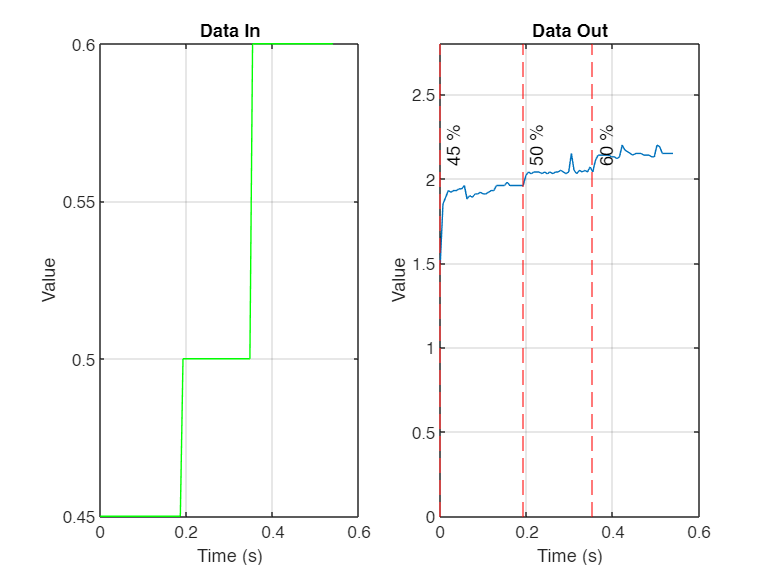

clc
clear all
close all
L = 36.5e-6;
C = 100e-6;
R=12;

load("bm7_cut.mat")

subplot(1,2,1)
plot(t, data_in(:,1),'Color','green');
xlabel('Time (s)');
ylabel('Value');
title('Data In');
grid on;

subplot(1,2,2)
plot(t, data_out(:,1));
xlabel('Time (s)');
ylim([0,2.8])
ylabel('Value');
title('Data Out');
grid on;

% Add vertical lines with text labels
hold on;
for i = 1:numel(x_values)
    xline(x_values(i), 'r--');  % Add vertical line at x-value
    text(x_values(i), max(data_out(:,1)), text_labels{i}, 'VerticalAlignment', 'cap', 'HorizontalAlignment', 'center','Rotation', 90);
end
hold off;


time_in_tmp = data_in(:,2);
data_in_tmp = data_in(:,1);
data_in(:,1) = time_in_tmp;
data_in(:,2)=data_in_tmp;

time_out_tmp = data_out(:,2);
data_out_tmp = data_out(:,1);
data_out(:,1) = time_out_tmp;
data_out(:,2)=data_out_tmp;